# Stock Data - Historical VaR

The 95% historical VaR represents the worst daily return you can expect from a stock at a confidence level of 95%. In this exercise, you will calculate the historic Value at Risk (VaR) for Magnum Hunter Resources Corporation stock returns. 

## 1.

Load data from `stockData_allCapSizes.mat`.

load stockData_allCapSizes.mat

## 2.

1.Extract the stock prices for Magnum Hunter Resources Corporation (ticker: MHR). Calculate the returns for this stock using the following:

`MHRret``= diff(log(MHR))`

MHR = stockPrices.MHR;

% Calculate the returns
MHRret = diff(log(MHR))

MHRret =          0
   -0.0328
    0.0328
   -0.0245
    0.0082
   -0.0165
   -0.0426
         0
   -0.1298
    0.0099


## 3. 

Calculate the 95% historical Value at Risk (VaR) by finding the quantile of the MHR returns at a threshold of 0.05.

alpha = 0.05;              % 5% cutoff
hVaR = quantile(MHRret,alpha)

hVaR = -0.0965

## 4. 

Return two outputs (the bin counts and edges) from the `histcounts`function (use 50 bins). Compute the center of each bin from the bin edges, and then identify the bin centers that are less than the 95% VaRthreshold found in step 3.

[binCounts, binEdges] = histcounts(MHRret, 50);
binCenters = (binEdges(1:end-1) + binEdges(2:end))/2;
% Find which bins are lower than VaR threshold.
lowerVaR = binCenters < hVaR;

## 5. 

Create two bar series to visualize the returns below the VaRin red, and the returns above the VaRin green. Display the VaRvalue in the title of the bar chart.

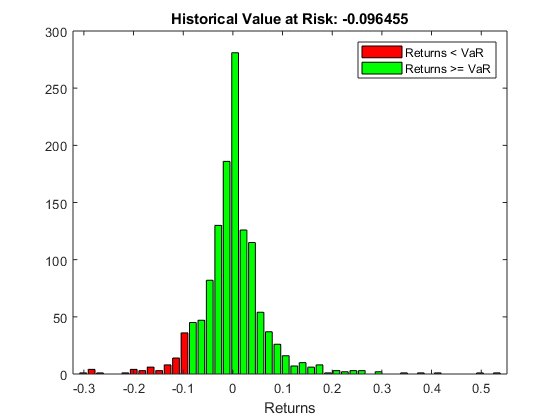

bar(binCenters(lowerVaR), binCounts(lowerVaR), 'r')
hold on
bar(binCenters(~lowerVaR), binCounts(~lowerVaR), 'g')
hold off
xlabel('Returns')
title(['Historical Value at Risk: ', num2str(hVaR)])
legend('Returns < VaR', 'Returns >= VaR')